%-----APLICANDO LAS PROPIEDADES 
clear all;
close all;
clc;
%-----Gráfica señal original-----
Fs=100;
t=-1:1/Fs:2;
A=3

A = 3

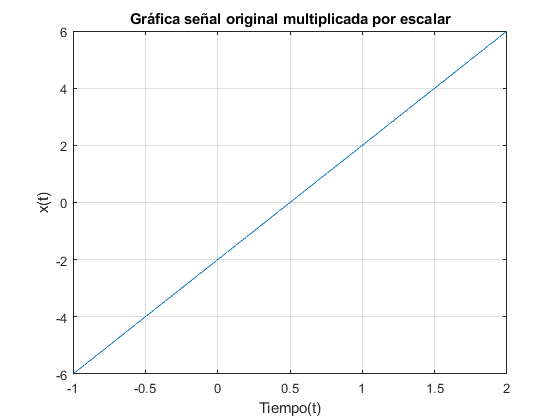

s=A*((4/3)*t-2/3);
plot(t,s);
title('Gráfica señal original multiplicada por escalar')
xlabel('Tiempo(t)');
ylabel('x(t)');
grid on

figure

%-----Multiplicación por escalar
syms t f;       %Variables simbólicas
e=-3;
xe= e*((4/3)*t-2/3);  %Señal por escalar
ye=int(xe*exp(-1i*2*pi*f*t),t,-1,2) %Transformada de Fourier teórica

$$ye = -\frac{{\mathrm{e}}^{-4\,\pi \,f\,\mathrm{i}}\,\left(1-{\mathrm{e}}^{6\,\pi \,f\,\mathrm{i}}+3\,\pi \,f\,\mathrm{i}+3\,\pi \,f\,{\mathrm{e}}^{6\,\pi \,f\,\mathrm{i}}\,\mathrm{i}\right)}{f^{2}\,\pi^{2}}$$

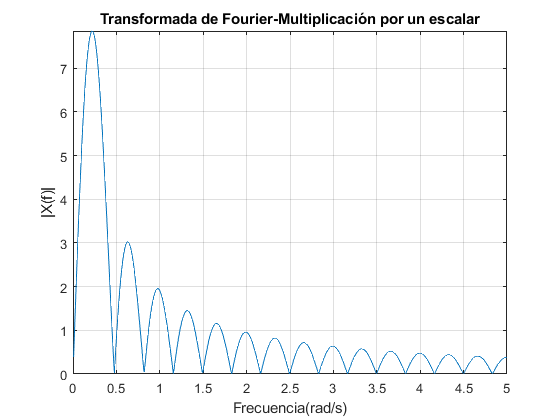

fplot(f,abs(ye),[0 5])
title('Transformada de Fourier-Multiplicación por un escalar')
xlabel('Frecuencia(rad/s)');
ylabel('|X(f)|');
grid on

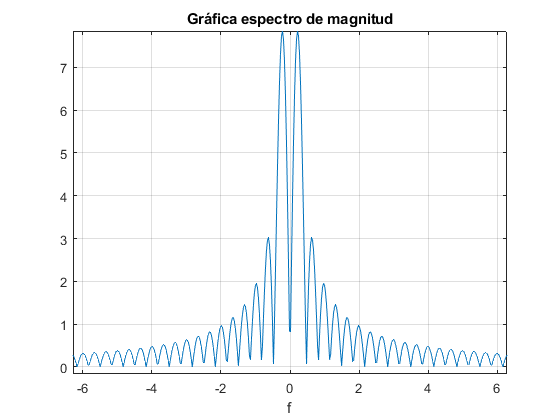

figure

%-----Gráfica espectro de magnitud
ezplot(abs(ye));
title('Gráfica espectro de magnitud')
grid on